**Лабораторная работа №1**

Дана следующая одномерная система:

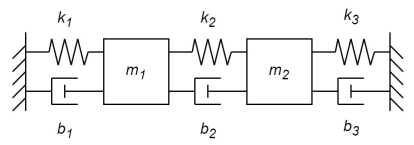

Задание:

- Вывести в аналитическом виде уравнение динамики системы

- Собрать имитационную модель из блоков MATLAB Simulink

- Собрать имитационную модель из блоков MATLAB Simscape

- Сравнить поведений моделей посредством:

- Отклонения от положения равновесия тела х, 2х, 5х. Величина отклонения х выражена в метрах или радианах, значение выбирается самостоятельно

- Импульсного внешнего воздействия (сила импульса воздействия 10 Н, длительность импульса 0,5 сек)

 **Аналитическое моделирование**

Функцию Лагранжа для всей системы можно записать в следующем виде:

$$L = L_1 + L_2 = K_1-P_1 + K_2-P_2$, где

$$L_1 = \frac{1}{2}m_1\dot{x_1}^2 - (\frac{1}{2}k_1x_1^2 + \frac{1}{2}k_2[x_1-x_2]^2)$$, $$L_2 = \frac{1}{2}m_2\dot{x_2}^2 - (\frac{1}{2}k_3x_2^2 + \frac{1}{2}k_2[x_1-x_2]^2)$$

Уравнения Эйлера-Лагранжа для механической системы можно записать в виде

$$\frac{d}{dt}\Big(\frac{\partial L}{\partial \dot{x}}\Big) - \frac{\partial L}{\partial {x}}= Q$$, где $Q$ - внешняя сила

$$\frac{d}{dt}\Big(\frac{\partial L_1}{\partial \dot{x}_1}\Big) = m\ddot{x}_1$$, $$\frac{\partial L_1}{\partial x_1} =-k_1x_1 - k_2[x_1-x_2]$$, $$Q_1 = -b_1 \dot{x}_1 - b_2[\dot{x}_1-\dot{x}_2] $$

$$\frac{d}{dt}\Big(\frac{\partial L_2}{\partial \dot{x}_2}\Big) = m\ddot{x}_2$$, $$\frac{\partial L_2}{\partial x_2} =-k_3x_2 + k_2[x_1-x_2]$$, $$Q_2 = -b_3 \dot{x}_2 + b_2[\dot{x}_1-\dot{x}_2] $$

Тогда итоговую систему можно переписать так


$$$\left\{\begin{array}{@{}ll@{}} m\ddot{x}_1 = -k_1x_1-k_2[x_1-x_2]-b_1\dot{x}_1-b_2[\dot{x}_1-\dot{x}_2] \\ m\ddot{x}_2 =-k_3x_2+k_2[x_1-x_2]-b_3\dot{x}_2+b_2[\dot{x}_1-\dot{x}_2] \end{array}\right.$$$


Задание начальных данных:

clc; clear all;
m1 = 20; m2 = 21; % kg 
b1 = 0.04; b2 = 3.57; b3 = 6.34; % N/(m/s)
k1 = 1e-9; k2 = 1e-9; k3 = 26.89; % N/m
dx1_0 = 0; dx2_0 = 0; % m/s
x1_0 = 5; x2_0 = 5; % m

F_1 = 0; F_2 = 10; % N
time_F_1 = 0.5; time_F_2 = 0.5; % s
t = 20; %s [simulation time]
% all time must be >0 !!!

Запуск модели:

F_1r = [F_1, 0]; F_1 = 0; F_2r = [F_2, 0]; F_2 = 0; 
x1 = [x1_0, x1_0 * 2, x1_0 * 5, 0];
x2 = [x2_0, x2_0 * 2, x2_0 * 5, 0];

x1_0 = x1(1); x2_0 = x2(1);

simu_1 = sim('simulink_block_diagram',...
    'StartTime','0','StopTime', num2str(t));
sims_1= sim('simscape_block_diagram',...
    'StartTime','0','StopTime', num2str(t));
x1_0 = x1(2); x2_0 = x2(2);
simu_2 = sim('simulink_block_diagram',...
    'StartTime','0','StopTime', num2str(t));
sims_2= sim('simscape_block_diagram',...
    'StartTime','0','StopTime', num2str(t));
x1_0 = x1(3); x2_0 = x2(3);
simu_3 = sim('simulink_block_diagram',...
    'StartTime','0','StopTime', num2str(t));
sims_3= sim('simscape_block_diagram',...
    'StartTime','0','StopTime', num2str(t));
F_1 = F_1r(1); F_2 = F_2r(1);
x1_0 = x1(4); x2_0 = x2(4);
simu_F = sim('simulink_block_diagram',...
    'StartTime','0','StopTime', num2str(t));
sims_F= sim('simscape_block_diagram',...
    'StartTime','0','StopTime', num2str(t));

Построение графиков положений и скоростей

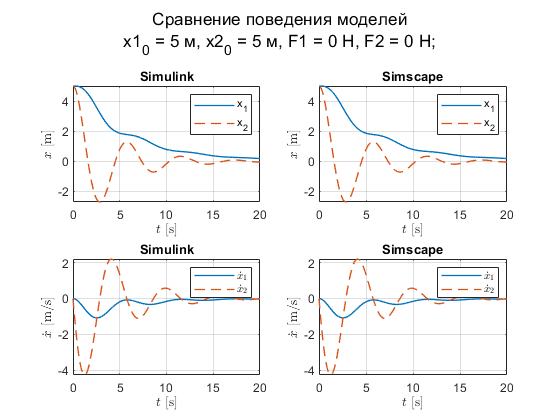

figure;
subplot(2,2,1)
plot(simu_1.simout.x1.time, simu_1.simout.x1.data,...
    'linewidth',1)
hold on
plot(simu_1.simout.x2.time, simu_1.simout.x2.data,...
    'linewidth', 1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('x_1','x_2');
title('Simulink');
subplot(2,2,3)
plot(simu_1.simout.dx1.time, simu_1.simout.dx1.data,...
    'linewidth',1)
hold on
plot(simu_1.simout.dx2.time, simu_1.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$', 'interpreter','latex');
title('Simulink');
subplot(2,2,2)
plot(sims_1.simout.x1.time, sims_1.simout.x1.data,...
    'linewidth',1)
hold on
plot(sims_1.simout.x2.time, sims_1.simout.x2.data,...
    'linewidth',1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('x_1','x_2');
title('Simscape');
subplot(2,2,4)
plot(sims_1.simout.dx1.time, sims_1.simout.dx1.data,...
    'linewidth',1)
hold on
plot(sims_1.simout.dx2.time, sims_1.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$', 'interpreter','latex');
title('Simscape');
sgtitle({['Сравнение поведения моделей'];...
    ['x1_0 = ', num2str(x1(1)),' м, x2_0 = ', num2str(x2(1)),' м, '...
    'F1 = ', num2str(F_1r(2)),' Н, F2 = ', num2str(F_2r(2)),' Н;']}) 

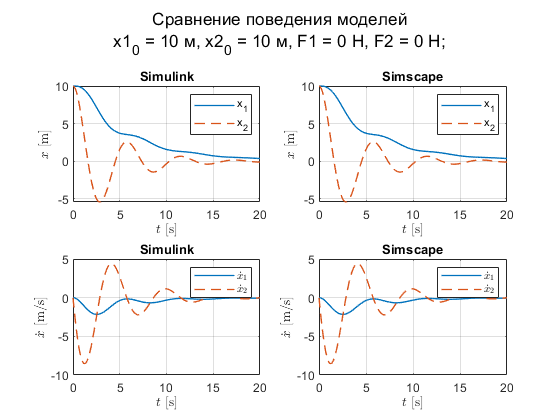



figure;
subplot(2,2,1)
plot(simu_2.simout.x1.time, simu_2.simout.x1.data,...
    'linewidth',1)
hold on
plot(simu_2.simout.x2.time, simu_2.simout.x2.data,...
    'linewidth', 1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('x_1','x_2');
title('Simulink');
subplot(2,2,3)
plot(simu_2.simout.dx1.time, simu_2.simout.dx1.data,...
    'linewidth',1)
hold on
plot(simu_2.simout.dx2.time, simu_2.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$', 'interpreter','latex');
title('Simulink');
subplot(2,2,2)
plot(sims_2.simout.x1.time, sims_2.simout.x1.data,...
    'linewidth',1)
hold on
plot(sims_2.simout.x2.time, sims_2.simout.x2.data,...
    'linewidth',1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('x_1','x_2');
title('Simscape');
subplot(2,2,4)
plot(sims_2.simout.dx1.time, sims_2.simout.dx1.data,...
    'linewidth',1)
hold on
plot(sims_2.simout.dx2.time, sims_2.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$', 'interpreter','latex');
title('Simscape');
sgtitle({['Сравнение поведения моделей'];...
    ['x1_0 = ', num2str(x1(2)),' м, x2_0 = ', num2str(x2(2)),' м, '...
    'F1 = ', num2str(F_1r(2)),' Н, F2 = ', num2str(F_2r(2)),' Н;']}) 

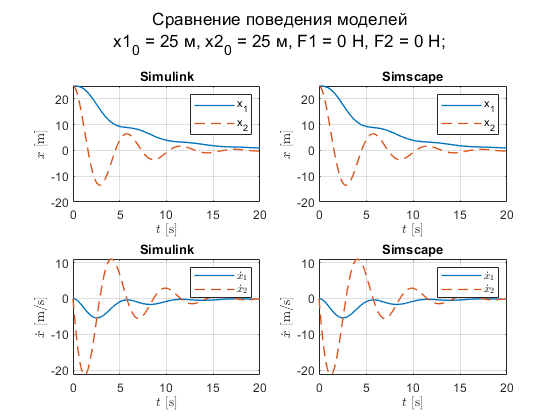



figure;
subplot(2,2,1)
plot(simu_3.simout.x1.time, simu_3.simout.x1.data,...
    'linewidth',1)
hold on
plot(simu_3.simout.x2.time, simu_3.simout.x2.data,...
    'linewidth', 1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('x_1','x_2');
title('Simulink');
subplot(2,2,3)
plot(simu_3.simout.dx1.time, simu_3.simout.dx1.data,...
    'linewidth',1)
hold on
plot(simu_3.simout.dx2.time, simu_3.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$', 'interpreter','latex');
title('Simulink');
subplot(2,2,2)
plot(sims_3.simout.x1.time, sims_3.simout.x1.data,...
    'linewidth',1)
hold on
plot(sims_3.simout.x2.time, sims_3.simout.x2.data,...
    'linewidth',1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('x_1','x_2');
title('Simscape');
subplot(2,2,4)
plot(sims_3.simout.dx1.time, sims_3.simout.dx1.data,...
    'linewidth',1)
hold on
plot(sims_3.simout.dx2.time, sims_3.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$', 'interpreter','latex');
title('Simscape');
sgtitle({['Сравнение поведения моделей'];...
    ['x1_0 = ', num2str(x1(3)),' м, x2_0 = ', num2str(x2(3)),' м, '...
    'F1 = ', num2str(F_1r(2)),' Н, F2 = ', num2str(F_2r(2)),' Н;']}) 

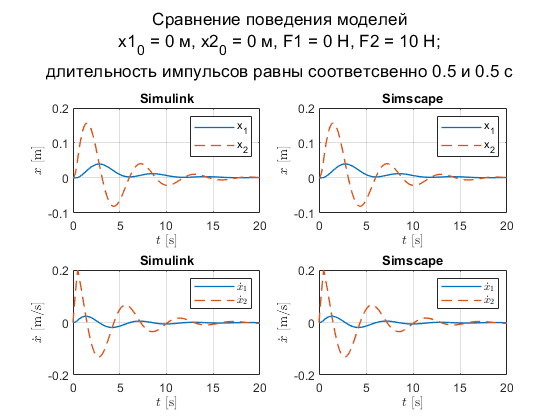



figure;
subplot(2,2,1)
plot(simu_F.simout.x1.time, simu_F.simout.x1.data,...
    'linewidth',1)
hold on
plot(simu_F.simout.x2.time, simu_F.simout.x2.data,...
    'linewidth', 1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('x_1','x_2');
title('Simulink');
subplot(2,2,3)
plot(simu_F.simout.dx1.time, simu_F.simout.dx1.data,...
    'linewidth',1)
hold on
plot(simu_F.simout.dx2.time, simu_F.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$', 'interpreter','latex');
title('Simulink');
subplot(2,2,2)
plot(sims_F.simout.x1.time, sims_F.simout.x1.data,...
    'linewidth',1)
hold on
plot(sims_F.simout.x2.time, sims_F.simout.x2.data,...
    'linewidth',1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('x_1','x_2');
title('Simscape');
subplot(2,2,4)
plot(sims_F.simout.dx1.time, sims_F.simout.dx1.data,...
    'linewidth',1)
hold on
plot(sims_F.simout.dx2.time, sims_F.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$', 'interpreter','latex');
title('Simscape');
sgtitle({['Сравнение поведения моделей'];...
    ['x1_0 = ', num2str(x1(4)),' м, x2_0 = ', num2str(x2(4)),' м, '...
    'F1 = ', num2str(F_1r(1)),' Н, F2 = ', num2str(F_2r(1)),' Н;']; ...
    ['длительность импульсов равны соответсвенно ', num2str(time_F_1),...
    ' и ',num2str(time_F_1),' с']}) 

Построение графиков усилий пружин и демпферов

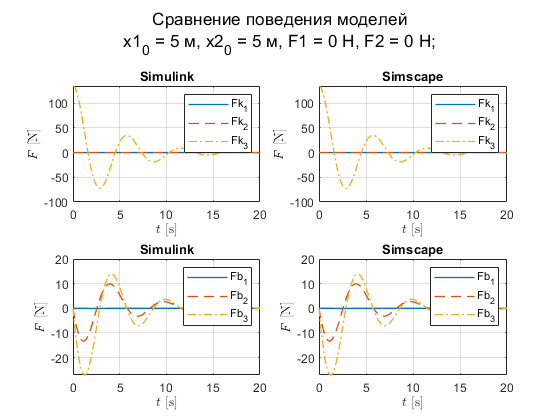


figure;
subplot(2,2,1)
plot(simu_1.simout.Fk1.time, simu_1.simout.Fk1.data,...
    'linewidth',1)
hold on
plot(simu_1.simout.Fk2.time, simu_1.simout.Fk2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_1.simout.Fk3.time, simu_1.simout.Fk3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fk_1','Fk_2','Fk_3');
title('Simulink');
subplot(2,2,3)
plot(simu_1.simout.Fb1.time, simu_1.simout.Fb1.data,...
    'linewidth',1)
hold on
plot(simu_1.simout.Fb2.time, simu_1.simout.Fb2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_1.simout.Fb3.time, simu_1.simout.Fb3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fb_1','Fb_2','Fb_3');
title('Simulink');
subplot(2,2,2)
plot(sims_1.simout.Fk1.time, sims_1.simout.Fk1.data,...
    'linewidth',1)
hold on
plot(sims_1.simout.Fk2.time, sims_1.simout.Fk2.data,...
    'linewidth', 1, "LineStyle","--")
plot(sims_1.simout.Fk3.time, sims_1.simout.Fk3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fk_1','Fk_2','Fk_3');
title('Simscape');
subplot(2,2,4)
plot(sims_1.simout.Fb1.time, sims_1.simout.Fb1.data,...
    'linewidth',1)
hold on
plot(sims_1.simout.Fb2.time, sims_1.simout.Fb2.data,...
    'linewidth', 1, "LineStyle","--")
plot(sims_1.simout.Fb3.time, sims_1.simout.Fb3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fb_1','Fb_2','Fb_3');
title('Simscape');
sgtitle({['Сравнение поведения моделей'];...
    ['x1_0 = ', num2str(x1(1)),' м, x2_0 = ', num2str(x2(1)),' м, '...
    'F1 = ', num2str(F_1r(2)),' Н, F2 = ', num2str(F_2r(2)),' Н;']}) 

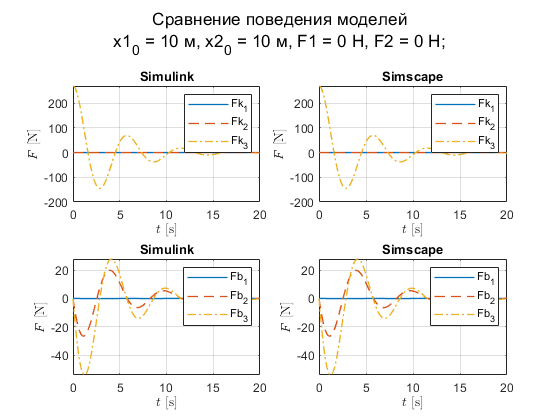




figure;
subplot(2,2,1)
plot(simu_2.simout.Fk1.time, simu_2.simout.Fk1.data,...
    'linewidth',1)
hold on
plot(simu_2.simout.Fk2.time, simu_2.simout.Fk2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_2.simout.Fk3.time, simu_2.simout.Fk3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fk_1','Fk_2','Fk_3');
title('Simulink');
subplot(2,2,3)
plot(simu_2.simout.Fb1.time, simu_2.simout.Fb1.data,...
    'linewidth',1)
hold on
plot(simu_2.simout.Fb2.time, simu_2.simout.Fb2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_2.simout.Fb3.time, simu_2.simout.Fb3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fb_1','Fb_2','Fb_3');
title('Simulink');
subplot(2,2,2)
plot(sims_2.simout.Fk1.time, sims_2.simout.Fk1.data,...
    'linewidth',1)
hold on
plot(sims_2.simout.Fk2.time, sims_2.simout.Fk2.data,...
    'linewidth', 1, "LineStyle","--")
plot(sims_2.simout.Fk3.time, sims_2.simout.Fk3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fk_1','Fk_2','Fk_3');
title('Simscape');
subplot(2,2,4)
plot(sims_2.simout.Fb1.time, sims_2.simout.Fb1.data,...
    'linewidth',1)
hold on
plot(sims_2.simout.Fb2.time, sims_2.simout.Fb2.data,...
    'linewidth', 1, "LineStyle","--")
plot(sims_2.simout.Fb3.time, sims_2.simout.Fb3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fb_1','Fb_2','Fb_3');
title('Simscape');
sgtitle({['Сравнение поведения моделей'];...
    ['x1_0 = ', num2str(x1(2)),' м, x2_0 = ', num2str(x2(2)),' м, '...
    'F1 = ', num2str(F_1r(2)),' Н, F2 = ', num2str(F_2r(2)),' Н;']})

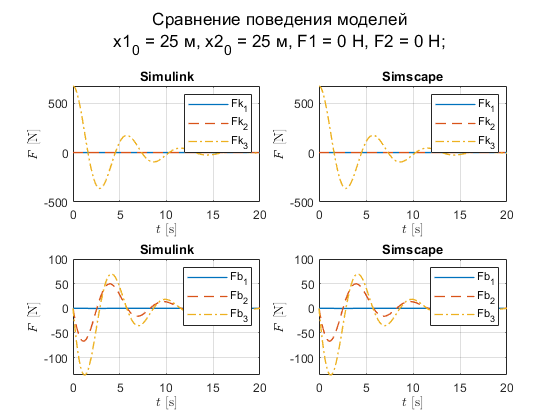


figure;
subplot(2,2,1)
plot(simu_3.simout.Fk1.time, simu_3.simout.Fk1.data,...
    'linewidth',1)
hold on
plot(simu_3.simout.Fk2.time, simu_3.simout.Fk2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_3.simout.Fk3.time, simu_3.simout.Fk3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fk_1','Fk_2','Fk_3');
title('Simulink');
subplot(2,2,3)
plot(simu_3.simout.Fb1.time, simu_3.simout.Fb1.data,...
    'linewidth',1)
hold on
plot(simu_3.simout.Fb2.time, simu_3.simout.Fb2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_3.simout.Fb3.time, simu_3.simout.Fb3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fb_1','Fb_2','Fb_3');
title('Simulink');
subplot(2,2,2)
plot(sims_3.simout.Fk1.time, sims_3.simout.Fk1.data,...
    'linewidth',1)
hold on
plot(sims_3.simout.Fk2.time, sims_3.simout.Fk2.data,...
    'linewidth', 1, "LineStyle","--")
plot(sims_3.simout.Fk3.time, sims_3.simout.Fk3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fk_1','Fk_2','Fk_3');
title('Simscape');
subplot(2,2,4)
plot(sims_3.simout.Fb1.time, sims_3.simout.Fb1.data,...
    'linewidth',1)
hold on
plot(sims_3.simout.Fb2.time, sims_3.simout.Fb2.data,...
    'linewidth', 1, "LineStyle","--")
plot(sims_3.simout.Fb3.time, sims_3.simout.Fb3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fb_1','Fb_2','Fb_3');
title('Simscape');
sgtitle({['Сравнение поведения моделей'];...
    ['x1_0 = ', num2str(x1(3)),' м, x2_0 = ', num2str(x2(3)),' м, '...
    'F1 = ', num2str(F_1r(2)),' Н, F2 = ', num2str(F_2r(2)),' Н;']})

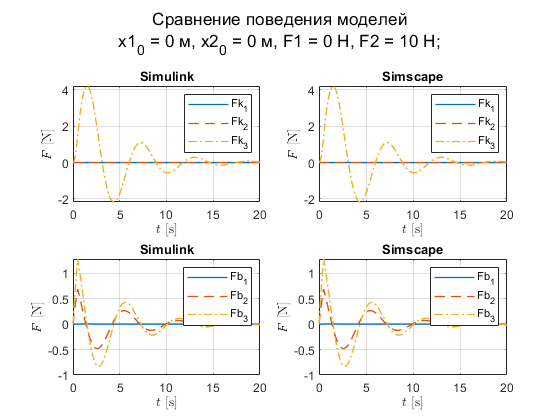



figure;
subplot(2,2,1)
plot(simu_F.simout.Fk1.time, simu_F.simout.Fk1.data,...
    'linewidth',1)
hold on
plot(simu_F.simout.Fk2.time, simu_F.simout.Fk2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_F.simout.Fk3.time, simu_F.simout.Fk3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fk_1','Fk_2','Fk_3');
title('Simulink');
subplot(2,2,3)
plot(simu_F.simout.Fb1.time, simu_F.simout.Fb1.data,...
    'linewidth',1)
hold on
plot(simu_F.simout.Fb2.time, simu_F.simout.Fb2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_F.simout.Fb3.time, simu_F.simout.Fb3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fb_1','Fb_2','Fb_3');
title('Simulink');
subplot(2,2,2)
plot(sims_F.simout.Fk1.time, sims_F.simout.Fk1.data,...
    'linewidth',1)
hold on
plot(sims_F.simout.Fk2.time, sims_F.simout.Fk2.data,...
    'linewidth', 1, "LineStyle","--")
plot(sims_F.simout.Fk3.time, sims_F.simout.Fk3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fk_1','Fk_2','Fk_3');
title('Simscape');
subplot(2,2,4)
plot(sims_F.simout.Fb1.time, sims_F.simout.Fb1.data,...
    'linewidth',1)
hold on
plot(sims_F.simout.Fb2.time, sims_F.simout.Fb2.data,...
    'linewidth', 1, "LineStyle","--")
plot(sims_F.simout.Fb3.time, sims_F.simout.Fb3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$F$ [N]','interpreter','latex');
grid on;
legend('Fb_1','Fb_2','Fb_3');
title('Simscape');
sgtitle({['Сравнение поведения моделей'];...
    ['x1_0 = ', num2str(x1(4)),' м, x2_0 = ', num2str(x2(4)),' м, '...
    'F1 = ', num2str(F_1r(1)),' Н, F2 = ', num2str(F_2r(1)),' Н;']})